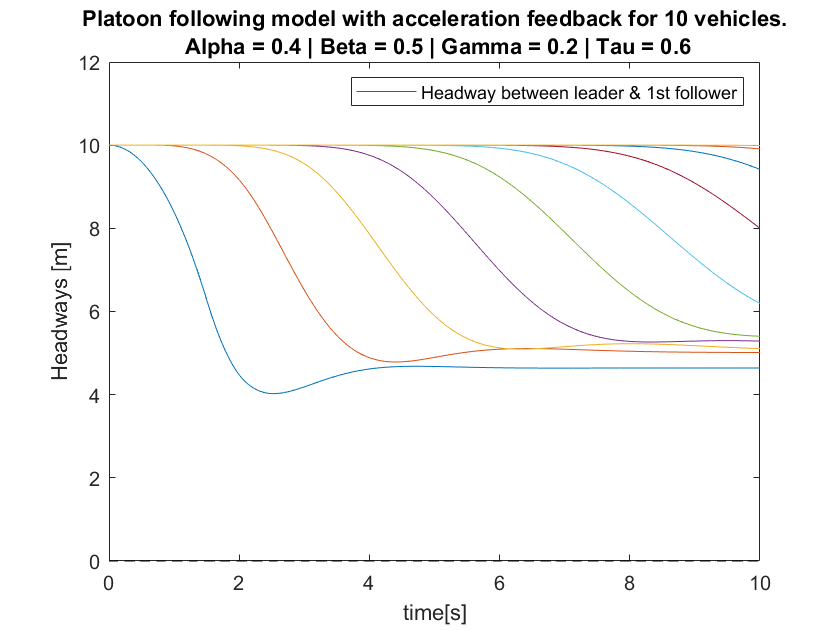

%Platoon following with acceleration feedback of leader.(Neutral Equation)
%Non Neutral -> ka(vLdot) -> works with dde23. 
%Neutral -> ka(vLdot - vdot) -> requies ddensd. ddensd gives ytaudot as
%solution as well.
%Refer HW6 Q2

clear; clc; close all;

follow_num=10;

kp=0.4;
kv=0.5;
ka=0.2; 
tau=0.6;

vmax=30;
hst=5;
kappa=0.6;
hgo=hst+vmax/kappa;

V=@(h)vmax*(hgo<=h) + kappa*(h-hst).*(hst<h & h<hgo);

vstar=15;
hstar=10;

amin = 8;
amax = 3;


deltat=0.01;
t0=0;
t1=1.5;
tend = 10;
tspan=t0:deltat:tend;


vl_acc = 10;    
vLead=(vstar-vl_acc*tspan).*(tspan<=t1);
vLeaddot = (-vl_acc).*(tspan<=t1);
vLeadtau=(tspan<t0+tau).*vstar+(t0+tau<=tspan).*interp1(tspan,vLead,tspan-tau,'linear','extrap');         
vLeadtaudot = @(t)(t<=t1+tau).*(-vl_acc+0*t);

v0=vstar*ones(1,follow_num);
h0=hstar*ones(1,follow_num);

f=@(t)[h0 v0];


sol = dde23(@(t,y,ytau)dde_func(t,y,ytau,tspan,vLead,vLeadtau,vLeadtaudot,vmax,amin,amax,kp,kv,ka,V,follow_num),tau,f,tspan);        
y = deval(sol,tspan);

headways = y(1:follow_num,:);
velocities = y(follow_num+1:end,:);

figure(1); hold on ; box on;
plot(tspan,headways);
plot(tspan,0.*tspan,'--k');
xlabel('time[s]');
ylabel('Headways [m]');
title({"Platoon following model with acceleration feedback for "+follow_num+...
    " vehicles."," Alpha = "+kp+" | Beta = "+kv+" | Gamma = "+ka+" | Tau = "+tau});
legend('Headway between leader & 1st follower');

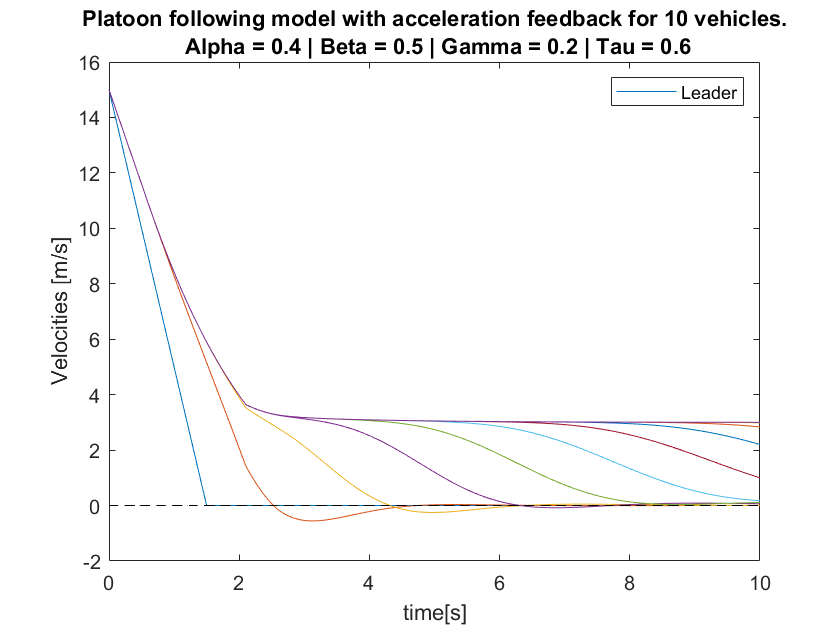


figure(2); hold on ; box on;
plot(tspan,vLead);
plot(tspan,velocities);
plot(tspan,0.*tspan,'--k');
xlabel('time[s]');
ylabel('Velocities [m/s]');
title({"Platoon following model with acceleration feedback for "+follow_num+...
    " vehicles."," Alpha = "+kp+" | Beta = "+kv+" | Gamma = "+ka+" | Tau = "+tau});
legend('Leader');

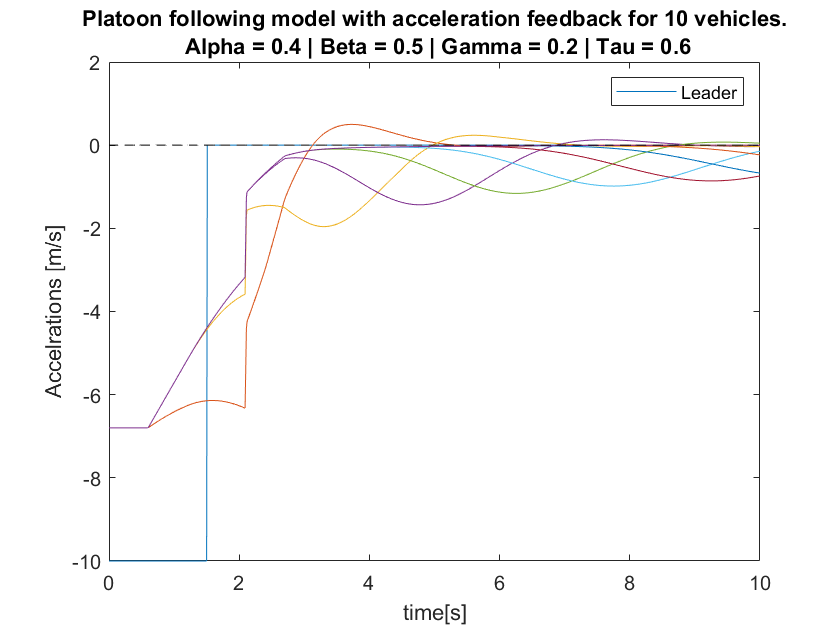


figure(3); hold on ; box on;
plot(tspan,vLeaddot);
plot(tspan,gradient(y(follow_num+1:2*follow_num,:)/deltat));
plot(tspan,0.*tspan,'--k');
xlabel('time[s]');
ylabel('Accelrations [m/s]');
title({"Platoon following model with acceleration feedback for "+follow_num+...
    " vehicles."," Alpha = "+kp+" | Beta = "+kv+" | Gamma = "+ka+" | Tau = "+tau});
legend('Leader');

function dydt = dde_func(t,y,ytau,tspan,vLead,vLeadtau,vLeadtaudot,...
            vmax,amin,amax,kp,kv,ka,V,follow_num)
        
    h=y(1:follow_num);       
    vF=y(follow_num+1:end);
    vL=[interp1(tspan,vLead,t,'linear','extrap');...
             vF(1:follow_num-1)];
    
    htau=ytau(1:follow_num);        
    vFtau=ytau(follow_num+1:end);
    vLtau=[interp1(tspan,vLeadtau,t,'linear','extrap');...
                vFtau(1:follow_num-1)];
 
    
    vLtaudot = vLeadtaudot(t); 
    
    W=@(vL)vL.*(vL<vmax)+vmax.*(vL>=vmax);
    u=@(h,v,vL,vLdot)kp*(V(h)-v) + kv*(W(vL)-v) + ka*(vLdot);
    
    sat=@(u)(u<-amin).*(-amin)+(-amin<=u & u<=amax).*u+(amax<u).*amax;
    
            
    dydt = [(vL-vF);
            (sat(u(htau,vFtau,vLtau,vLtaudot)))];

end
        


